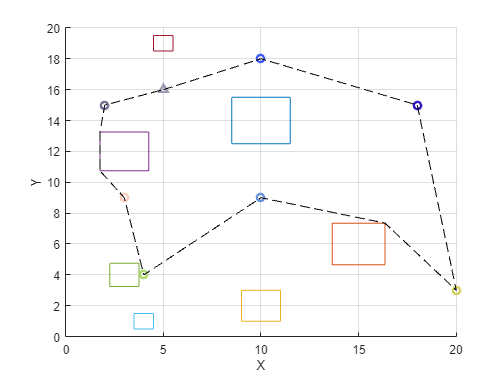

clear
clc
close all
% Specify input parameters
gridsize = [20, 20];

pickup = [5, 16];

dropoff = [3,  9;
          18, 15; 
          20,  3; 
           4,  4; 
          10, 18;
           2, 15
          10,  9];

avoid = [3,  4,  1.5; 
         3,  12,  2.5; 
         4,  1,  1;
        10,  2,  2;
        10, 14,  3;
         5, 19,  1;
        15,  6,  2.7];


% The following user-defined function is path planning software aimed to
% optimize the path between a pickup zone and various drop off zones while
% avoiding specified areas.

%--------------------------------------------------------------------------%
%                             INPUTS GUIDE                                 %
%--------------------------------------------------------------------------%
% gridsize :  a 1x2 vector containing the width and height of the grid to be
% used
%
%
% pickup :  an 1x2 vector containing the X and Y coordinate of the pickup
% location within the specified grid
%
%
% dropoff :  an nx2 matrix containing n rows of X and Y coordinates for n
% dropoff locations
%
%
% avoid :  an mx3 matrix containing m rows of X and Y coordinates with the
% third column representing the side length of the obstacle to avoid
% (obstacles are assumed to be square)
%
% --> e.g.  an obstacle at (3, 5) with a side length of 2 and an obstacle
% at (7, 8) with a side length of 1 would be represented as:
%      [3, 5, 2; 7, 8, 1]


%--------------------------------------------------------------------------%
%                            OUTPUTS GUIDE                                 %
%--------------------------------------------------------------------------%
% GPS :  a px2 matrix containing the coordinates of the optimized path
%
%
% Path Graph :  a visualization of the optimized path




%--------------------------------------------------------------------------%
%                            MAIN FUNCTION                                 %
%--------------------------------------------------------------------------%

% Determine permutaion of every drop off index
prm = perms(1:length(dropoff));

% Generate lines for avoidance
avoid_lines_main = zeros(5, 2, size(avoid, 1));
for i = 1:size(avoid, 1)
    s = avoid(i, 3)/2;
    x = avoid(i, 1);
    y = avoid(i, 2);
    
    bl = [x - s, y - s];
    tl = [x - s, y + s];
    tr = [x + s, y + s];
    br = [x + s, y - s];
   
    avoid_lines_main(:, : , i) = [bl; tl; tr; br; bl];
    
end

% Initialize final variable
GPS = [];
shortest = 1e6;

% Generate the coordinate path by looping through every permutation order
% and determineing minimum total distance
for p = 1:length(prm)

    % Generate the coordinate path
    GPS_temp = pickup;
    c = 0;

    % Determine pathing index for this iteration
    path_index = prm(p, :);

    for i = 2:length(dropoff)+2
        if i == length(dropoff)+2
            GPS_temp = [GPS_temp; pickup];
        else
            GPS_temp = [GPS_temp; dropoff(path_index(i-1), :)];
        end
    
        % Determine direction of travel
        xs = GPS_temp(i + c, 1) - GPS_temp(i + c - 1, 1);
        ys = GPS_temp(i + c, 2) - GPS_temp(i + c - 1, 2);
    
        % Determine function of current path
        fx = @(x) (GPS_temp(i + c, 2) - GPS_temp(i + c - 1, 2))/(GPS_temp(i + c, 1) - GPS_temp(i + c - 1, 1)).*(x - GPS_temp(i + c - 1, 1)) + GPS_temp(i + c - 1, 2);
        fy = @(y) (GPS_temp(i + c, 1) - GPS_temp(i + c - 1, 1))/(GPS_temp(i + c, 2) - GPS_temp(i + c - 1, 2)).*(y - GPS_temp(i + c - 1, 2)) + GPS_temp(i + c - 1, 1);
    
        % Sort the obstacles in order from closest to farthest on current
        % pathway
        dist_dropoff_avoid = pdist2(GPS_temp(i + c - 1, :), avoid(:, 1:2));
        dist_dropoff_avoid_main = dist_dropoff_avoid;
    
        % Sort through the obstacles
        avoid_lines = zeros(size(avoid_lines_main));
        for m = 1:size(avoid, 1)
    
            [~, sort] = min(dist_dropoff_avoid);
            dist_dropoff_avoid_main(m) = dist_dropoff_avoid(sort);
            dist_dropoff_avoid(sort) = NaN;
            avoid_lines(:, :, m) = avoid_lines_main(:, :, sort);
    
        end
        dist_current = pdist2(GPS_temp(i + c - 1, :), GPS_temp(i + c, :));
    
        % Determine intersection points for each obstacle
        for j = 1:size(avoid, 1)
    
            % Determine case based on direction of travel
    
            % If current path moves right and up (additional conditions ensure proper avoidance)
            if xs >= 0 && ys >= 0 && GPS_temp(i + c - 1, 1) <= avoid_lines(3, 1, j) && GPS_temp(i + c - 1, 2) <= avoid_lines(3, 2, j) && dist_current > dist_dropoff_avoid_main(j)
                
                % Determine possible point of intersection for left side of
                % object
                x = avoid_lines(1, 1, j);
                fX = fx(x);
                
                % Determine possible point of intersection for bot side of
                % object
                y = avoid_lines(1, 2, j);
                fY = fy(y);
    
                % Check current path intersects with left side
                if fX >= avoid_lines(1, 2, j) && fX < avoid_lines(2, 2, j)
                    
                    % If left side intersection, determine proper maneuver for
                    % avoidance and update GPS list accordingly
                    if GPS_temp(i + c, 1) <= avoid_lines(3, 1, j) || GPS_temp(i + c, 2) >= avoid_lines(2, 2, j)
                  
                        GPS_temp = [GPS_temp(1:i + c - 1, :); avoid_lines(2, :, j); GPS_temp(i + c, :)];
                        c = c + 1;
    
                    else
    
                        GPS_temp = [GPS_temp(1:i + c - 1, :); avoid_lines(2, :, j); avoid_lines(3, :, j); GPS_temp(i + c, :)];
                        c = c + 2;
    
                    end
    
                % Check if current path intersects with bot side
                elseif fY > avoid_lines(5, 1, j) && fY < avoid_lines(4, 1, j)
    
                    % If bot side intersection, determine proper maneuver for
                    % avoidance and update GPS list accordingly
                    if GPS_temp(i + c, 2) <= avoid_lines(3, 2, j) || GPS_temp(i + c, 1) >= avoid_lines(3, 1, j)
                        
                        GPS_temp = [GPS_temp(1:i + c - 1, :); avoid_lines(4, :, j); GPS_temp(i + c, :)];
                        c = c + 1;
    
                    else
    
                        GPS_temp = [GPS_temp(1:i + c - 1, :); avoid_lines(4, :, j); avoid_lines(3, :, j); GPS_temp(i + c, :)];
                        c = c + 2;
    
                    end
    
                end
               
            % If current path moves right and down (additional conditions ensure proper avoidance)
            elseif xs >= 0 && ys <= 0 && GPS_temp(i + c - 1, 1) <= avoid_lines(3, 1, j) && GPS_temp(i + c - 1, 2) >= avoid_lines(1, 2, j) && dist_current > dist_dropoff_avoid_main(j)
    
                % Determine possible point of intersection for left side of
                % object
                x = avoid_lines(1, 1, j);
                fX = fx(x);
    
                % Determine possible point of intersection for top side of
                % object
                y = avoid_lines(2, 2, j);
                fY = fy(y);
    
                % Check if current path intersects with left side of object
                if fX > avoid_lines(1, 2, j) && fX <= avoid_lines(2, 2, j)
    
                    % If left side intersection, determine proper maneuver for
                    % avoidance and update GPS list accordingly
                    if  GPS_temp(i + c, 1) <= avoid_lines(4, 1, j) || GPS_temp(i + c, 2) <= avoid_lines(4, 2, j)
    
                        GPS_temp = [GPS_temp(1:i + c - 1, :); avoid_lines(5, :, j); GPS_temp(i + c, :)];
                        c = c + 1;
                
                    else
    
                        GPS_temp = [GPS_temp(1:i + c - 1, :); avoid_lines(5, :, j); avoid_lines(4, :, j); GPS_temp(i + c, :)];
                        c = c + 2;
                    
                    end
                
                % Check if current path intersects with top side of object
                elseif fY > avoid_lines(5, 1, j) && fY < avoid_lines(4, 1, j)
    
                    % If top side intersection, determine proper maneuver for
                    % avoidance and update GPS list accordingly
                    if GPS_temp(i + c, 2) >= avoid_lines(4, 2, j) || GPS_temp(i + c, 1) >= avoid_lines(4, 1, j)
                        
                        GPS_temp = [GPS_temp(1:i + c - 1, :); avoid_lines(3, :, j); GPS_temp(i + c, :)];
                        c = c + 1;
    
                    else
    
                        GPS_temp = [GPS_temp(1:i + c - 1, :); avoid_lines(3, :, j); avoid_lines(4, :, j); GPS_temp(i + c, :)];
                        c = c + 2;
                    
                    end
    
                end
    
     
            % If current path moves left and down (additional conditions ensure proper avoidance)
            elseif xs <= 0 && ys <= 0 && GPS_temp(i + c - 1, 1) >= avoid_lines(2, 1, j) && GPS_temp(i + c - 1, 2) >= avoid_lines(1, 2, j) && dist_current > dist_dropoff_avoid_main(j)
    
                % Determine possible point of intersection for right side of
                % object
                x = avoid_lines(3, 1, j);
                fX = fx(x);
    
                % Determine possible point of intersection for top side of
                % object
                y = avoid_lines(2, 2, j);
                fY = fy(y);
            
                % Check if current path intersects with right side of object
                if fX > avoid_lines(4, 2, j) && fX <= avoid_lines(3, 2, j)
    
                    % If right side intesection, determine proper maneuver for
                    % avoidance and update GPS list accordingly
                    if GPS_temp(i + c, 1) >= avoid_lines(5, 1, j) || GPS_temp(i + c, 2) <= avoid_lines(5, 2, j)
    
                        GPS_temp = [GPS_temp(1:i + c - 1, :); avoid_lines(4, :, j); GPS_temp(i + c, :)];
                        c = c + 1;
    
                    else
    
                        GPS_temp = [GPS_temp(1:i + c - 1, :); avoid_lines(4, :, j); avoid_lines(5, :, j); GPS_temp(i + c, :)];
                        c = c + 2;
    
                    end
                
                % Check if current path intersects with top side of object
                elseif fY > avoid_lines(2, 1, j) && fY < avoid_lines(3, 1, j)
    
                    % If top side intersection, determine proper maneuver for
                    % avoidance and update GPS list accordingly
                    if GPS_temp(i + c, 2) >= avoid_lines(1, 2, j) || GPS_temp(i + c, 1) <= avoid_lines(5, 1, j)
                        
                        GPS_temp = [GPS_temp(1:i + c - 1, :); avoid_lines(2, :, j); GPS_temp(i + c, :)];
                        c = c + 1;
    
                    else
    
                        GPS_temp = [GPS_temp(1:i + c - 1, :); avoid_lines(2, :, j); avoid_lines(1, :, j); GPS_temp(i + c, :)];
                        c = c + 2;
    
                    end
    
                end
    
            % If current path moves left and up (additional conditions ensure proper avoidance)
            elseif xs <= 0 && ys >= 0 && GPS_temp(i + c - 1, 1) >= avoid_lines(1, 1, j) && GPS_temp(i + c - 1, 2) <= avoid_lines(3, 2, j) && dist_current > dist_dropoff_avoid_main(j)
    
                % Determine possible point of intersection for right side of
                % object
                x = avoid_lines(3, 1, j);
                fX = fx(x);
    
                % Determine possible point of intersection for bot side of
                % object
                y = avoid_lines(1, 2, j);
                fY = fy(y);
    
                % Check if current path intersects with right side of object
                if fX >= avoid_lines(4, 2, j) && fX < avoid_lines(3, 2, j)
    
                    % If right side intersection, determine proper maneuver for
                    % avoidance and update GPS list accordingly
                    if GPS_temp(i + c, 1) >= avoid_lines(2, 1, j) || GPS_temp(i + c, 2) >= avoid_lines(2, 2, j)
    
                        GPS_temp = [GPS_temp(1:i + c - 1, :); avoid_lines(3, :, j); GPS_temp(i + c, :)];
                        c = c + 1;
    
                    else
    
                        GPS_temp = [GPS_temp(1:i + c - 1, :); avoid_lines(3, :, j); avoid_lines(2, :, j); GPS_temp(i + c, :)];
                        c = c + 2;
    
                    end
    
                % Check if current path intersects with bot side of object
                elseif fY > avoid_lines(5, 1, j) && fY < avoid_lines(4, 1, j)
    
                    % If right side intersection, determine proper mnaneuver
                    % for avoidance and update GPS list accordingly
                    if GPS_temp(i + c, 2) <= avoid_lines(2, 2, j) || GPS_temp(i + c, 1) <= avoid_lines(2, 1, j)
                        
                        GPS_temp = [GPS_temp(1:i + c - 1, :); avoid_lines(1, :, j); GPS_temp(i + c, :)];
                        c = c + 1;
    
                    else
    
                        GPS_temp = [GPS_temp(1:i + c - 1, :); avoid_lines(1, :, j); avoid_lines(2, :, j); GPS_temp(i + c, :)];
                        c = c + 2;
    
                    end
    
                end
    
            end
    
        end
    
    end

    % Determine total distance of current GPS path
    dist_tot = 0;
    for q = 2:length(GPS_temp)
        dist_tot = dist_tot + pdist2(GPS_temp(q - 1, :), GPS_temp(q, :));
    end
    
    % Check if the new path is a shorter distance than the previous
    % shortest path
    if shortest > dist_tot

        % If shorter, store path and store new shortest value
        GPS = GPS_temp;
        shortest = dist_tot;

    end

end


%--------------------------------------------------------------------------%
%                                PLOTTING                                  %
%--------------------------------------------------------------------------%

% Establish variable for use in plotting
p = [pickup; dropoff];
colors = rand(length(dropoff) + 1, 3);

% Plot all avoidance objects
hold on
for i = 1:size(avoid, 1)
    plot(avoid_lines(:, 1, i), avoid_lines(:, 2, i))
end

% Plot the pickup and drop off locations
for i = 1:length(dropoff) + 1
    if i == 1
        plot(p(i, 1), p(i, 2), '^', 'Color', colors(i, :), 'LineWidth', 2)
    else
        plot(p(i, 1), p(i, 2), 'o', 'Color', colors(i, :), 'LineWidth', 2)
    end
end

% Plot the path lines
plot(GPS(:, 1), GPS(:, 2), 'k--'), grid
axis([0 gridsize(1) 0 gridsize(2)]), xlabel('X'), ylabel('Y')
hold off


% End Function
GPS

GPS =     5.0000   16.0000
   10.0000   18.0000
   18.0000   15.0000
   20.0000    3.0000
   16.3500    7.3500
   10.0000    9.0000
    4.0000    4.0000
    3.0000    9.0000
    1.7500   10.7500
    1.7500   13.2500
